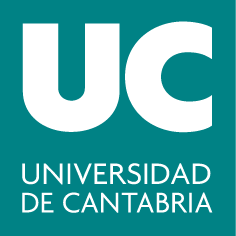

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Métodos Matemáticos para Ingeniería**

**Bloque II: Métodos Numéricos**

# **5. Integración numérica de ecuaciones diferenciales ordinarias **

*Dpto. Matemática Aplicada y Ciencias de la Computación*

## Introducción

Las ecuaciones diferenciales ordinarias (EDO) son ecuaciones que relacionan una función desconocida con sus derivadas respecto a una sola variable independiente. La forma general de una EDO de nnn-ésimo orden es: 


$$$$F(x,y,y',\ldots, y^{(n)}) = 0$$$$


- x es la variable independiente.

- $y(x)$ es la función desconocida.

- $n$ es el orden de la ecuación, que indica la derivada de mayor orden presente en la ecuación.

Las EDO de orden superior pueden transformarse en un sistema de ecuaciones de primer orden. Para ello, se introduce un conjunto de nuevas variables que representan las derivadas sucesivas de la función desconocida:


$$ \begin{cases}
   y_1(x) & = y(x), \\
   y_2(x) & = \frac{dy}{dx}, \\
\ldots\\
   y_{n}(x) & = \frac{d^{n-1}y}{dx^{n-1}}.
   \end{cases}$$


A partir de las definiciones de las nuevas variables, el sistema de ecuaciones de primer orden se obtiene de la siguiente manera:


$$\[
\begin{cases}
\frac{dy_1}{dx}  = y_2, \\
\frac{dy_2}{dx}  = y_3, \\
\frac{dy_3}{dx}  = y_4, \\
 \vdots \\
\frac{dy_{n-1}}{dx}  = y_n, \\
\frac{dy_n}{dx}  = f(x, y_1, y_2, \ldots, y_n).
\end{cases}
\]$$


Definimos un vector $$Y = [y_1, y_2, \ldots, y_n]^T$$, entonces $Y' = [y_1', y_2', \ldots, y_n']^T$. Con esta notación el sistema se escribe en la forma matricial:

$Y' = F(x,Y)$. 

**Ejemplo: **Consideremos la ecuación diferencial de segundo orden: $$$m \frac{d^2y}{dx^2} + c \frac{dy}{dx} + ky = 0$$$

Podemos reducir esta ecuación de segundo orden a un sistema de primer orden al introducir una nueva variable $g$, donde:


$$$g = \frac{dy}{dx}$, $\frac{d^2y}{dx} = \frac{dg}{dx}$$$


El sistema resultante es:


$$\begin{cases}
m \frac{dg}{dx} + cg + ky = 0\\
\frac{dy}{dx}  =g
\end{cases}$$


**Solución de la EDO**

La solución de una EDO es una función que satisface la ecuación diferencial dada. Al integrar la ecuación, se introduce una  (o varias) constante de integración, que indica que la solución no es única, sino que hay una familia de soluciones.

Para obtener una solución única, se necesita información adicional en forma de **condiciones auxiliares**:

- Para EDO de primer orden, se especifica un **valor inicial**.

- Para EDO de $n$-ésimo orden, se requieren $n$ condiciones adicionales:

- **Problemas de valor inicial (PVI)**: todas las condiciones se dan en el mismo valor de la variable independiente.

- **Problemas de valor frontera (PVF)**: las condiciones se especifican en diferentes valores de la variable independiente.

## 5.1. Problemas de valor inicial

Problema de Cauchy  o Problema de Valor Inicial (PVI) consiste en encontrar una función $\( y(x) \)$ que satisfaga una ecuación diferencial ordinaria junto con una **condición inicial** específica:


$$$$\frac{dy}{dx} = f(x,y), \quad y(x_0) = y_0, \; x \in [x_0, x_f]$$$$


El PVI define un punto de partida $\( (x_0, y_0) \)$ desde el cual la solución de la ecuación diferencial comienza a evolucionar. La solución buscada es una función $\( y(x) \)$ que satisface tanto la ecuación diferencial en todo el intervalo $\( I  = [x_0, \, x_f]\) $como la condición inicial en $\( x_0 \)$.

Teorema de Existencia y Unicidad: Supongamos que $f(x,y)$ es continua en el rectángulo $R = \{(x,y): \, x_0 \leq x\leq x_f, \; c  \leq y \leq d\}$. Si $f$ verifica una condición de Lipschitz con respecto a su variable $y$ en $R$ :


$$\exists L>0: \; |f(x,y_1) - f(x,y_2)| \leq L |y_1 - y_2|, \quad \forall (x,y_1), (x,y_2)\in R$$


Si $(x_0, y_0) \in R$, entonces el PVI $$$\frac{dy}{dx} = f(x,y), \quad y(x_0) = y_0$$$ tiene una solución única $y = y(x)$en algún subintervalo $x_0 \leq x_0 + \delta$.

La solución numérica se obtiene usando el esquema:

Partiendo del valor inicial,  Nuevo valor = valor anterior + pendiente $$\times$$ tamaño de paso.

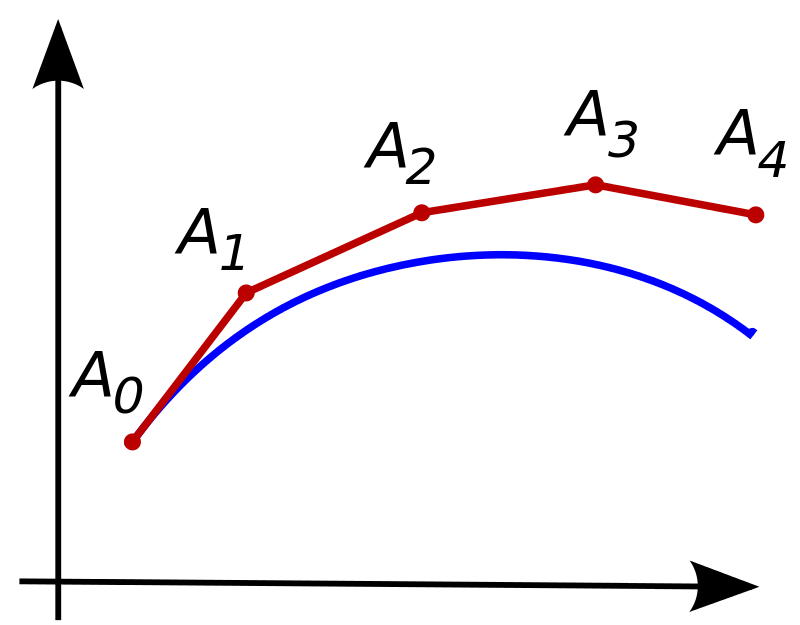

La solución numérica de las EDO implica dos tipos de error:

**Errores de truncamiento**, o de discretización, originados por la naturaleza de las técnicas empleadas para aproximar los valores de $$y$$.

- ET local que resulta de una aplicación del método considerado, en un solo paso

- ET propagado que resulta de las aproximaciones producidas durante los pasos previos

- ET global = ET local + ET propagado

**Errores de redondeo**, causados por el número limitado de cifras significativas que una computadora puede retener.

**Convergencia**

Se dice que el método es **convergente ** si para todo problema de Cauchy con $$f$$ suficientemente regular se tiene


$$$$\max_{n} ||y(x_n) - y_n || \rightarrow 0, \quad h \rightarrow 0$$$$


 Se  dice que el método es deorden $$p$ $si para toda función $$f$$ definiendo la ecuación diferencial se tiene


$$$$\max_{n} ||y(x_n) - y_n || = O(h^p)$$$$


#### Método de Euler

El primer método que estudiaremos es el **método de Euler**. Aunque no se utiliza con frecuencia en la práctica debido a que su solución tiende a acumular errores significativos a lo largo del proceso, es fundamental conocerlo por varias razones:

- El método de Euler permite un análisis del error más sencillo en comparación con otros métodos más avanzados.

- A través del estudio de este método, podemos ilustrar una serie de conceptos clave en la resolución numérica de ecuaciones diferenciales.

Sea $[x_0, x_f]$ el intervalo en el que queremos hallar la solución de un PVI. Dividimos este intervalo en $$n$$ subintervalos de ancho  $$h = \frac{x_f-x_0}{N}$ (h se llama también tamaño de paso):


$$$$x_n = x_0 + nh, \quad n =0, \ldots, N$$$$


Suponiendo que  $y(x), y'(x), y''(x)$ son continuas y usamos el teorema de Taylor para desarrollar $y(x)$ alrededor de $x = x_0$:


$$y(x) = y(x_0) + y'(x_0)(x-x_0) + \frac{y''(\xi)}{2}(x-x_0)^2,\quad \xi \in [x_0, x]$$


De la ecuación se tiene: $y'(x_0) = f(x_0, y_0)$. Sustituyendolo en el polinomio de Tayor y teniendo en cuenta que $h = x_1 - x_0$, se obtiene:


$$y(x_1) = y(x_0) + hf(x_0,y_0) + \frac{y''(\xi)}{2}h^2,\quad \xi \in [x_0, x]$$


Si el tamaño de paso es  suficientemente pequeño, podemos despreciar el término que contiene $h^2$:


$$y(x_1) = y(x_0) + hf(x_0,y_0) $$


Repitiendo el proceso generamos una sucesión de puntos que se aproximan a la gráfica de la solución $y = y(x)$. El paso general del método de Euler es:


$$\begin{cases}
x_{n+1} = x_n + h,\\
y_{n+1} = y_n + h f(x_n, y_n),  \;n = 0,\ldots, n-1
\end{cases}$$


**Ejercicio: **Resolver en forma analítica el problema siguiente, en el intervalo de $$x = 0$$ a 2:


$$$$\frac{dy}{dx} = yx^2 -1.1 y, \quad y(0) = 1$$$$


Graficar la solución.

Utilizar el método de Euler con$ $h = 0.5$ y $0.05$$, para resolver el problema. Graficar los resultados en la misma gráfica para comparar en forma visual la exactitud de los dos tamaños de paso.

clear all
close all
x0 = 0; xf = 2;
% define la solución analítica: 
% sol = @(x)
y0 = 1;

% escribe aquí el código....





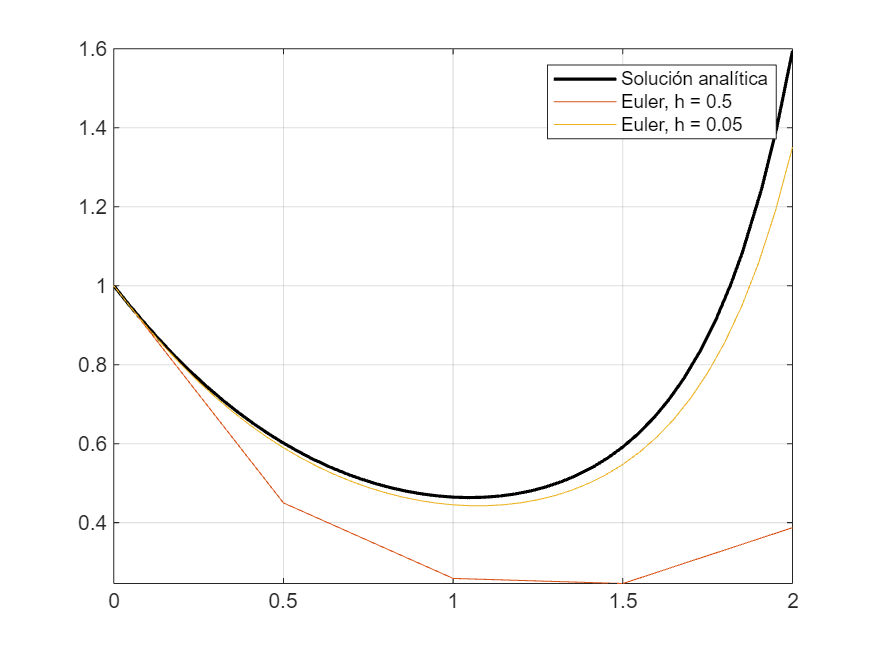

eje51()

Ir a "eje51"

**Análisis del error para el método de Euler**

La serie de Taylor respecto a un valor inicial$ $(x_n, y_n)$$:


$$$$y_{n+1} = y_n +  y'(x_n)h + \frac{y''(\xi)}{2!}h^2$$$$


Sustituyendo $$y'(x_n)$ $por $$f(x_n,y_n)$$:


$$$$\underbrace{y_{n+1} = y_n +  f(x_n,y_n)h}_{\text{método de Euler}} + \underbrace{\frac{y''(\xi)}{2!}h^2 }_{\text{ET local}}$$$$


ET local es $$O(h^2)$$. Se puede demostrar que el ET global es  $$O(h)$$.

#### Método de Heun

La siguiente técnica que presentamos, el método de Heun, sigue la idea:

 Nuevo valor = valor anterior + pendiente $$\times$$ tamaño de paso.

Para aproximar la pendiente se promedian las derivadas en dos puntos para obtener una mejor estimación de la pendiente en el intervalo:


$$y_{n+1} = y_n + h \times \frac{f(x_n,y_n) + f(x_{n+1}, y_{n+1}^0)}{2}$$


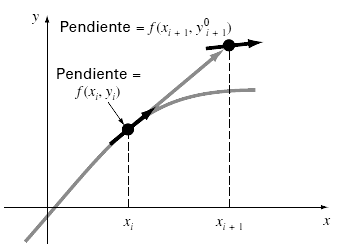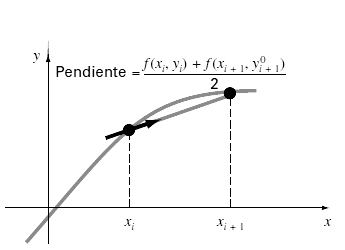

Para aproximar (predicir) el valor $y_{n+1}^0$ se utiliza el método de Euler. Así, el paso general del **método de Heun** es:

Predictor: $y_{n+1}^0 = y_n + h f(x_n, y_n)$

Corrector: $y_{n+1} = y_n + h \times \frac{f(x_n,y_n) + f(x_{n+1}, y_{n+1}^0)}{2}$

Por eso, el metodo de Heun también es conocido como el **método de predicción-corrección**.

En situaciones como los polinomios, donde la EDO es únicamente  función de la variable independiente, no se requiere el paso predictor y el corrector se aplica sólo una vez en cada iteración:


$$$$y_{n+1} = y_n +\frac{f(x_n) + f(x_{n+1})}{2}h$$$$


Errores del método de Heun:

- ET local:$ $O(h^3)$$

- ET global: $$O(h^2)$$

**Ejercicio: **Utilizar el método de Heun con $ $h = 0.5$ $, para resolver el problema en el intervalo de $$x = 0$$ a 2:


$$$$\frac{dy}{dx} = yx^2 -1.1 y, \quad y(0) = 1$$$$


Graficar los resultados (solución analítica, Método de Euler con $h=0.5$, Método de Heun con $h= 0.5$) en la misma gráfica para comparar en forma visual la exactitud de los dos tamaños de paso.

clear all
close all
x0 = 0; xf = 2;
% define la solución analítica: 
% sol = @(x)
y0 = 1;

% escribe aquí el código....




Comprobar los resultados:

x =          0    0.5000    1.0000    1.5000    2.0000


y_heun =     1.0000    0.6294    0.4866    0.6073    1.4754


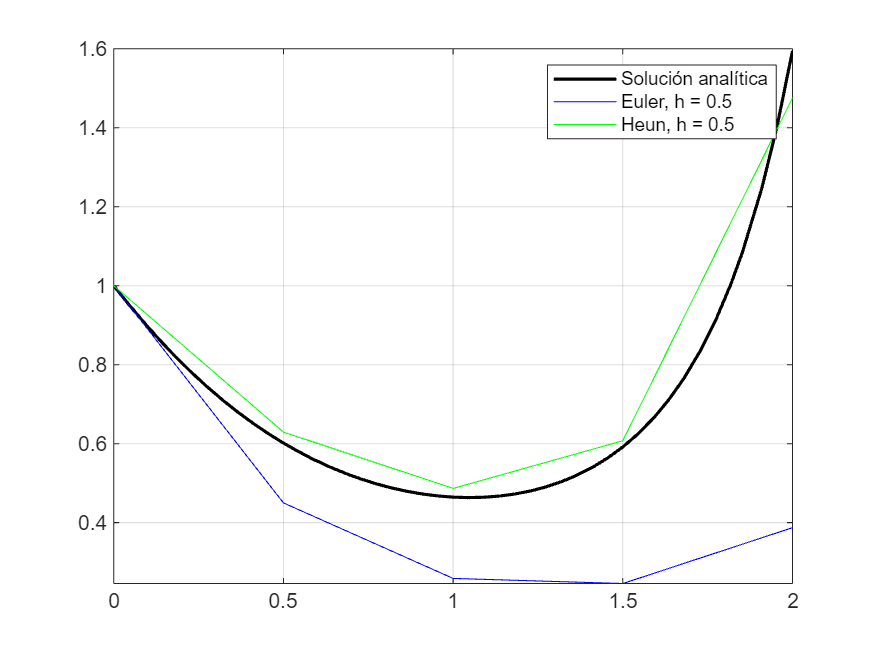

eje52()

Ir a "eje52"

#### Método del punto medio

En el método del punto medio, la pendiente se aproxima en el punto medio:


$$$y_{n+1/2} = y_n + f(x_n,y_n)\frac{h}{2}$$$


y luego se aplica el esquema " Nuevo valor = valor anterior + pendiente $$\times$$ tamaño de paso":


$$y_{n+1} = y_n+ f(x_{n+1/2},y_{n+1/2})h$$


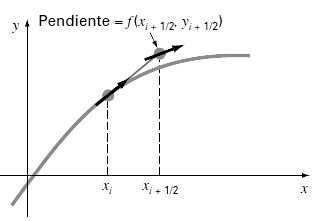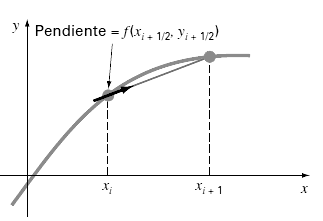

Errores del método del punto medio:

- ET local:$ $O(h^3)$$

- ET global: $$O(h^2)$$

**Ejercicio: **Modificar el código anterior para implementar el método del punto medio  con $ $h = 0.5$ $(en lugar del método de Heun). Comparar los resultados.

clear all
close all
x0 = 0; xf = 2;
% define la solución analítica: 
% sol = @(x)
y0 = 1;

% escribe aquí el código....





#### Métodos de Runge-Kutta

Los métodos de Runge-Kutta (RK) logran la exactitud del procedimiento de la serie de Taylor sin necesitar el cálculo de derivadas de orden superior. Existen muchas variantes, pero todas tienen la forma generalizada:


$$
$$y_{n+1} = y_n + \phi(x_n, y_n,h)h$$$$


donde $$\phi(x_n, y_n,h)$$ se conoce como función incremento, la cual puede interpretarse como una pendiente representativa en el intervalo:


$$$$\phi(x_n, y_n,h) = b_1 k_1 + b_2 k_2 + \ldots + b_m k_m = \sum_{i=1}^m b_i k_i$$$$


donde

- 
$$$k_1 = f(x_n, y_n)$$$


- 
$$$k_2 = f(x_n + c_2 h, y_n + a_{21}k_1h)$$$


- 
$$ $\ldots$$$


1. **Primer orden** - Método de Euler

2. **Segundo orden (RK2):** $$$y_{n+1} = y_n + (b_1k_1 + b_2k_2)h$$$

- 
$$ $k_1 = f(x_n, y_n)$$$


- 
$$ $k_2 = f(x_n + c_2 h, y_n + a_{21}k_1h)$$$


Los coeficientes se evalúan al igualar la ecuación con la expansión de la serie de Taylor (4 incogitas, 3 condiciones):


$$ $b_1 = 1-b_2$, $c_2 = a_{21} = \frac{1}{2b_2}$, $b_2$ - libre$$


Así, hay un número infinito de métodos RK de segundo orden.

- Método de Heun ($$b_2= 1/2$$)

El resto de coeficientes: $ $b_1=1/2$, $c_2=1$,  $a_{21}=1$$


$$$$y_{n+1} = y_n + \left(\frac{1}{2}k_1 + \frac{1}{2}k_2\right)h$$$$



$$$k_1 = f(x_n, y_n)$$$



$$$k_2 = f(x_n + h, y_n + k_1h)$$$


**Ejemplo**: Implementamos el método de Heun usando las fórmulas de Runge-Kutta:

clear all
close all
sol = @(x2) exp(x2.^3/3-1.1*x2);
x0 = 0; xf = 2;
y0 = 1;
f = @(x2,y) y.*(x2.^2-1.1);
fplot(sol,[x0,xf],'k-','LineWidth',1.5)
grid on
hold on
h = 0.5;
x = x0:h:xf;
n = length(x);

% Método de Heun:
b = [1/2, 1/2];
c2 = 1;
a21 = 1;
y= zeros(1, n);
y(1) = y0;
for k = 1:n-1
    k1 = f(x(k), y(k)); % Etapa 1
    k2 = f(x(k) + c2*h, y(k) + a21*h*k1); % Etapa 2
    % avance:
    y(k+1) = y(k) + b*[k1; k2]*h;

end
plot(x,y,'g-')
legend('Solución analítica',  'Heun, h = 0.5')
hold off

- Método del punto medio ($$b_2= 1$$)

Coeficientes: $ $b_1=0$, $c_2=1/2$,  $a_{21}=1/2$$


$$$$y_{n+1} = y_n + k_2h$$$$



$$ $k_1 = f(x_n, y_n)$$$



$$$k_2 = f\left(x_n +\frac{1}{2}h, y_n +\frac{1}{2} k_1h\right)$$$


- Método de Ralston ($$b_2= 2/3$$)

Coeficientes: $ $b_1=1/3$, $c_2=3/4$,  $a_{21}=3/4$$


$$$$y_{n+1} = y_n + \left(\frac{1}{3}k_1 + \frac{2}{3}k_2\right)h$$$$



$$$k_1 = f(x_n, y_n)$$$



$$$k_2 = f\left(x_n +\frac{3}{4}h, y_n +\frac{3}{4} k_1h\right)$$$


**Ejercicio: **Modifica el código anterior para realizar el método de Ralston: 

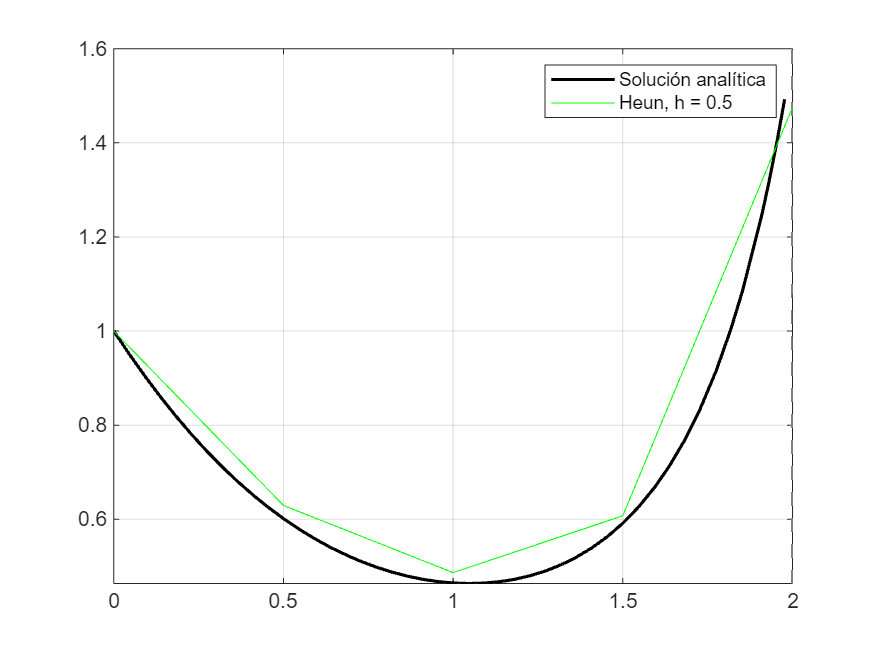

% clear all
% close all
% sol = @(x2) exp(x2.^3/3-1.1*x2);
% x0 = 0; xf = 2;
% y0 = 1;
% f = @(x2,y) y.*(x2.^2-1.1);
% fplot(sol,[x0,xf],'k-','LineWidth',1.5)
% grid on
% hold on
% h = 0.5;
% x = x0:h:xf;
% n = length(x);
% 
% % Método de Heun:
% b = [1/2, 1/2];
% c2 = 1;
% a21 = 1;
% y= zeros(1, n);
% y(1) = y0;
% for k = 1:n-1
%     k1 = f(x(k), y(k)); % Etapa 1

%     k2 = f(x(k) + c2*h, y(k) + a21*h*k1); % Etapa 2
%     % avance:
%     y(k+1) = y(k) + b*[k1; k2]*h;
% 
% end
% plot(x,y,'g-')
% legend('Solución analítica',  'Heun, h = 0.5')
% hold off

3. **Métodos de Runge-Kutta de tercer orden (RK3)**

Para $$m = 3$ $(tres etapas), es posible efectuar un desarrollo similar al del método de segundo orden. El resultado de tal desarrollo genera seis ecuaciones con ocho incógnitas. Por lo tanto, se deben dar a priori los valores de dos de las incógnitas con la finalidad de establecer los parámetros restantes. Una versión común que se obtiene es


$$$$y_{n+1} = y_n + \frac{1}{6} \left( k_1 + 4 k_2 + k_3 \right)h$$$$


- 
$$$k_1 = f(x_n, y_n)$$$


- 
$$ $k_2 = f\left(x_n +\frac{1}{2}h, y_n +\frac{1}{2} k_1h\right)$$$


- 
$$$k_3 = f\left(x_n + h, y_n -k_1h + 2k_2 h\right)$$$


**Ejercicio**: Implementa el método RK3 para el ejemplo anterior.

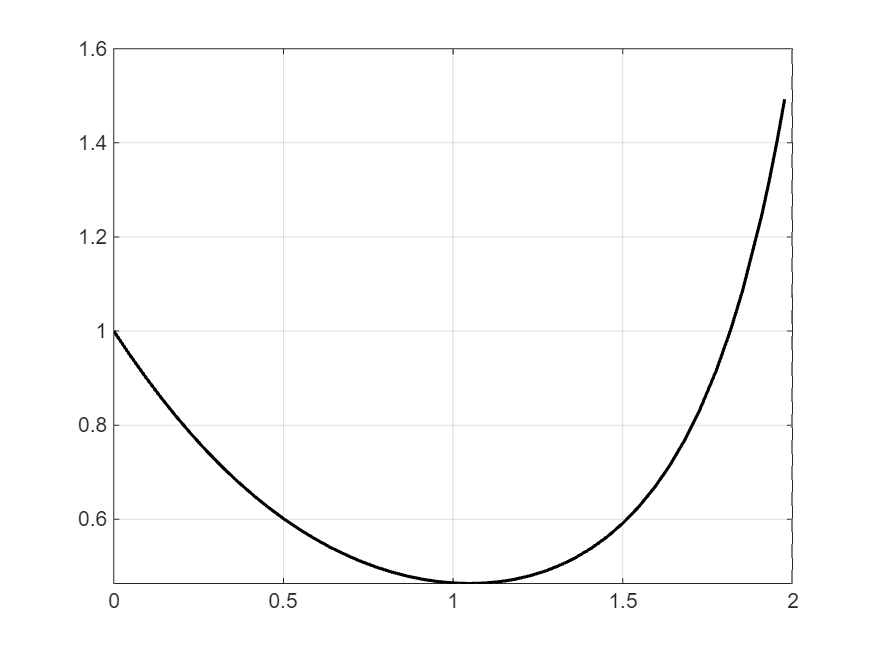

clear all
close all
sol = @(x2) exp(x2.^3/3-1.1*x2);
x0 = 0; xf = 2;
y0 = 1;
f = @(x2,y) y.*(x2.^2-1.1);
fplot(sol,[x0,xf],'k-','LineWidth',1.5)
grid on
hold on
h = 0.5;
x = x0:h:xf;
n = length(x);

% Método RK3:
% escribe aquí el código...



hold off

4. **Métodos de Runge-Kutta de cuarto orden (RK4)**

El más popular de los métodos RK es el de cuarto orden:


$$$$y_{n+1} = y_n +\frac{1}{6} \left( k_1 + 2 k_2 + 2k_3 + k_4\right)h$$$$



$$$k_1 = f(x_n, y_n)$$$



$$$k_2 = f\left(x_n +\frac{1}{2}h, y_n +\frac{1}{2} k_1 h\right)$$$



$$ $k_3 = f\left(x_n + \frac{1}{2}h, y_n +\frac{1}{2}k_2 h\right)$$$



$$$k_4 =  f\left(x_n + h, y_n +k_3 h\right)$$$


**Ejercicio**: Implementa el método RK4 para el ejemplo anterior.

clear all
close all
sol = @(x2) exp(x2.^3/3-1.1*x2);
x0 = 0; xf = 2;
y0 = 1;
f = @(x2,y) y.*(x2.^2-1.1);
fplot(sol,[x0,xf],'k-','LineWidth',1.5)
grid on
hold on
h = 0.5;
x = x0:h:xf;
n = length(x);

% Método RK4:
% escribe aquí el código...



hold off

#### Tablero de  Butcher

El **Tablero de Butcher** es una representación tabular utilizada para describir métodos de integración numérica en el contexto de ecuaciones diferenciales ordinarias, particularmente para los **métodos de Runge-Kutta**. Este tablero facilita la presentación y comprensión de las fórmulas de estos métodos.**Estructura del Tablero de Butcher**

Un tablero de Butcher para un método de Runge-Kutta de orden sss se organiza de la siguiente manera:

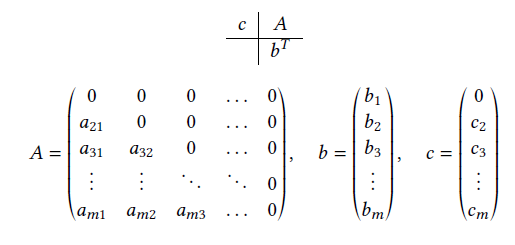

Donde:

- $a_{ij}$: Son los coeficientes que determinan las combinaciones lineales de los incrementos intermedios $k_j$ que contribuyen a la solución.

- $b_i$: Son los coeficientes de ponderación para la combinación lineal final que calcula el valor aproximado de $y_{n+1}$.

- $c_i$: Son los coeficientes, que indican los puntos en los que se evalúa la función $f(x,y)$ dentro del intervalo de integración.

El método toma la siguiente forma


$$ $x_{n,i} = x_n +c_i h, \quad 1 \leq i \leq m$$$



$$ $k_{n,1} = f(x_n,y_n)$$$



$$$k_{n,i} = f(x_{n,i}, \; y_n + h \sum_{j=1}^{i-1} a_{ij}k_{n,j}), \quad 2 \leq i \leq m$$$



$$ $y_{n+1} = y_n + h \sum_{j=1}^m b_j k_{n,j}$$$


**Ejercicio: **Escribe los tabletos de Butcher para todos los métodos de Runge-Kutta mencionados (Euler, Heun, RK4...).

Salvo alguna excepción de poca importancia práctica, todos los métodos Runge-Kutta satisfacen que


$$$$\sum_j a_{ij} = c_i, \quad 1 \leq i \leq m$$$$


Adicionalmente, las siguientes  ecuaciones deben cumplirse para que el método alcance el orden indicado:

Orden 1: $$b^T e = 1$,$

Orden 2: Orden 1 +  $$b^Tc = 1/2$$,

Orden 3: Orden 2 + $ $b^Tc^2=1/3$, $b^TAc = 1/6$$,

Orden 4:  Orden 3 + $ $b^Tc^3=1/4$,  $b^TAc^2=1/12$,  $b^TA^2c=1/24$,  $(b\cdot c)^TAc=1/8$,$

Una posible implementación del método RK en MatLAB:	

#### Métodos de paso variable

Los métodos de paso variable son técnicas avanzadas para resolver ecuaciones diferenciales que buscan adaptar el tamaño del paso de integración en función de la precisión deseada. Una estrategia efectiva en este contexto es el uso **de pares encajados** de métodos Runge-Kutta (RK).

El objetivo principal de los pares encajados es ajustar dinámicamente el tamaño del paso de integración para mejorar la precisión y la eficiencia computacional. La idea general es calcular dos predicciones para cada paso utilizando métodos Runge-Kutta de diferente orden. Estos métodos proporcionan aproximaciones a la solución de una ecuación diferencial, pero con diferentes grados de precisión.

**Algoritmo:**

**1. Definición de los parámetros: **Se fijan dos parámetros $$\varepsilon_a$$ (error absoluto) y $$\varepsilon_r$$ (error relativo) que determinan la tolerancia del error de integración en cada instante $$x_n$$. 

Elección del tamaño del paso inicial $$h_0$$:

$$$h_0 = \max \left\lbrace \left[ \varepsilon_a + \varepsilon_r ||y_0|| \right]^{\frac{1}{p+1}, \; h_{\min}} \right\rbrace$$$,  donde podemos fijar $$h_{\min} = \frac{b-a}{10^6}$$ por ejemplo.

**2. Cálculo de Predicciones**: Para un paso dado, se utilizan dos métodos Runge-Kutta (normalmente, los coeficientes $A$ y $c$ son los mismos, coeficientes $b$ - diferentes $ b_j\neq \hat{b}_j $) : 


$$$$
\begin{cases}
y_{n+1} = y_n + h_n \phi(x_n, y_n, h_n)
\\
\hat{y}_{n+1} = y_n + h_n \psi(x_n, y_n, h_n)
\end{cases}$$


el primero de orden $$p$$ y el segundo de orden $$q > p$$.

**3. Estimación del Error Local**: Una vez obtenidas las dos predicciones, se resta una de la otra para estimar el error local de la integración:


$$$$\epsilon_{n+1} = || \hat{y}_{n+1} - y_{n+1}||  = h_n \sum_{j=1}^m (\hat{b}_j - b_j) k_j$$$$


**4. Ajuste del Tamaño del Paso**: Basado en la estimación del error local, el tamaño del paso se ajusta. Si el error estimado es menor que un umbral predefinido (indicado por una tolerancia TOL), la solución se acepta. Si el error es mayor que el umbral, el paso se reduce para mejorar la precisión. Para 

Si  $$\epsilon_{n+1} < \; TOL =  \varepsilon_a + \varepsilon_r ||\hat{y}_{n+1}||$$ $$\rightarrow$$ Se acepta el paso.

Si  $$\epsilon_{n+1} > \; TOL$ $\rightarrow$$ Se rechaza el paso:

- $$h_n = \min \left\lbrace r_n, \; r_{\min} \right\rbrace h_n,$$ donde $$r_n =0.9 \frac{TOL}{||\epsilon_{n+1}||}, \quad r_{\min} = 0.5$$

**5. Previsión del paso siguiente**:  Si ha habido un fallo del paso en la determinación de una de las dos últimas aproximaciones de la solución, entonces se toma $$r_{\max} = 1$$, en caso contrario $$r_{\max} = 5$$. Se calcula $$r_n$$ como antes y se toma


$$$$h_{n+1} = 
\begin{cases}
h_n, & \text{si } r_n \in [-1,1]\\
\min \left\lbrace r_n, r_{\max}\right\rbrace h_n, & \text{en otro caso}
\end{cases}
$$$$


Una posuble implementación del método Runge-Kutta con  paso variable:

#### Método de Runge-Kutta-Fehlberg (RKF45)

En ejemplo de los métodos con paso variable es el método de Runge-Kutta-Fehlberg (RKF, RKF45). Este método combina un método de Runge-Kutta de cuarto orden con uno de quinto orden. Este método está realizado en la función de MATLAB [`ode45`](https://es.mathworks.com/help/matlab/ref/ode45.html)`.`

- `odefun`: es un manejador de la función  que evalúa el segundo miembro de la ecuación, $$f(x; y)$$. Puede ser el nombre de una función anónima dependiente de dos variables, siendo `x` la primera de ellas e `y` la segunda, o también una M-función, en cuyo caso se escribiría `@odefun`.

- `[x0,xf]` es el intervalo en el que se quiere resolver la ecuación

- `y0` es el valor de la condición inicial

Si se desean conseguir los valores $$x$$ e $$y$$ de la aproximación numérica para usos posteriores, se debe usar la función \texttt{ode45} en la forma:

Si se utiliza la función `ode45` en esta forma, **no se obtiene ninguna gráfica**.

- `options`: un conjunto de opciones que puede especificar la tolerancia, el tamaño máximo del paso y otras configuraciones del algoritmo. Esto se puede definir mediante la función `odeset:`

**Ejemplo:** Resolver el problema siguiente, en el intervalo de $$x = 0$$ a 2:


$$$$\frac{dy}{dx} = yx^2 -1.1 y, \quad y(0) = 1$$$$


usando la función `ode45:`

clear all
close all
sol = @(x2) exp(x2.^3/3-1.1*x2);
x0 = 0; xf = 2;
y0 = 1;
f = @(x2,y) y.*(x2.^2-1.1);
fplot(sol,[x0,xf],'k-','LineWidth',1.5)
grid on
hold on

ode45(f,[x0,xf],y0);

Se obtiene la representación gráfica, pero no se guardan los valores de $x$ e $y$. Para guardarlos:

[x,y] = ode45(f,[x0,xf],y0)

x =          0
    0.0457
    0.0913
    0.1370
    0.1827
    0.2327
    0.2827
    0.3327
    0.3827
    0.4327


y =     1.0000
    0.9510
    0.9046
    0.8608
    0.8196
    0.7774
    0.7383
    0.7021
    0.6688
    0.6383


Y ahora si queremos representar los resultados:

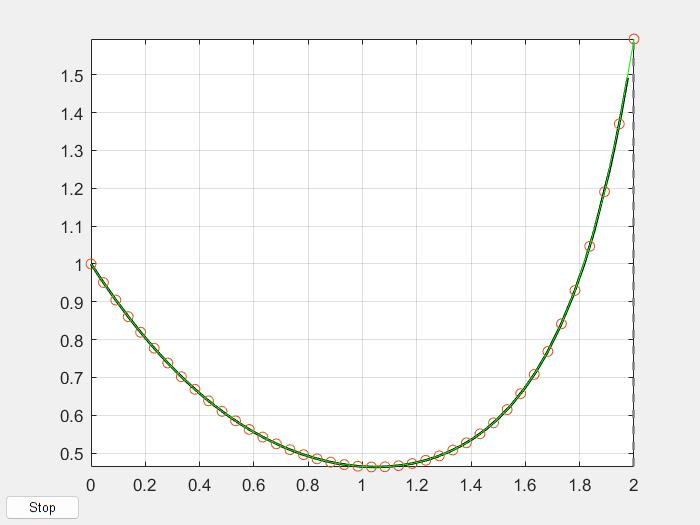

plot(x,y,'g')

 Gracias a las capacidades vectoriales del lenguaje MATLAB, estos problemas también pueden resolverse utilizando la función `ode45`. Solo es necesario expresar el problema en forma vectorial:


$$$$Y' = F(x,Y), \quad Y(x_0) = Y^0$$$$


**Ejemplo**: Calcular (una aproximación de) la solución del problema


$$$$
\begin{cases}
y_1' = y_2 y_3\\
y_2' = -0.7y_1 y_3\\
y_3' = -0.51 y_1 y_2
\end{cases}, 
\quad
\begin{cases}
y_1(0) = 0\\
y_2(0) = 1\\
y_3(0) = 1
\end{cases}
$$$$


en $$[0, \; 5\pi]$$.

Definimos el vector $Y = [y_1, y_2, y_3]^T$, el vector de las condiciones iniciales $Y^0 = [0, \;1, \;1]^T$ y la función $F(x, Y) = \left[ Y(2) \cdot Y(3);   \;-0.7 \cdot Y(1)\cdot Y(3); \; -0.51\cdot Y(1) \cdot Y(2) ]^T$. Entonces, el problema se escribe como $$$Y' = F(x,Y), \quad Y(x_0) = Y^0$$$. Y se puede usar la función  `ode45 `para resolverlo numericamente:

clear all 
close all
% Definimos la función del sistema (un vector-columna de 3 elementos):
f = @(x,y) [ y(2)*y(3);         % primera ecuación
			 -0.7*y(1)*y(3);    % segunda ecuación
			 -0.51*y(1)*y(2)];  % tercera ecuación
% Definimos el vector-columna de las condiciones iniciales:
y0 = [ 0; 1; 1]; % número de elementos = número de ecuaciones = números de funciones en el vector Y
[x,y] = ode45(f, [0, 5*pi], y0);

Se obtiene el vector $x$, que contiene los valores de las abscisas (tiempos o puntos de evaluación), y la matriz $y$, que tiene un número de columnas igual al número de funciones en el vector $Y$. La primera columna de $y$ contiene los valores de la primera función $y_1$ en los puntos especificados en $x$; la segunda columna contiene los valores de la segunda función $y_2$, etc. Representamos las soluciones numéricas:

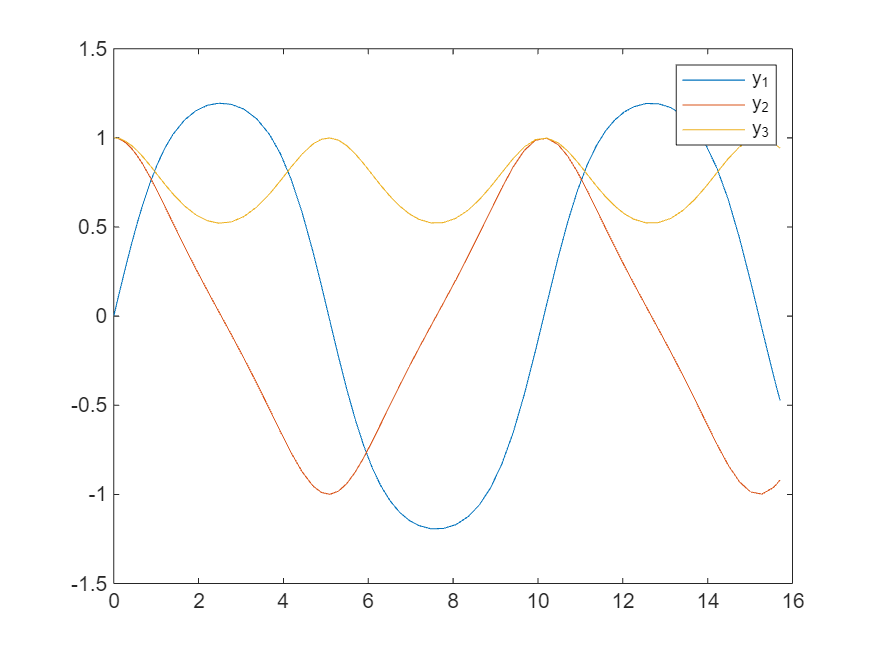

plot(x,y)
legend('y_1', 'y_2', 'y_3')

Ya hemos visto que las EDOs de orden superior se pueden reescribir como un sistema de ecuaciones de primer orden introduciendo un conjunto de nuevas variables que representan las derivadas sucesivas de la función desconocida:


$$ \begin{cases}
   y_1(x) & = y(x), \\
   y_2(x) & = \frac{dy}{dx}, \\
\ldots\\
   y_{n}(x) & = \frac{d^{n-1}y}{dx^{n-1}}.
   \end{cases}$$


A partir de las definiciones de las nuevas variables, el sistema de ecuaciones de primer orden se obtiene de la siguiente manera:


$$\[
\begin{cases}
\frac{dy_1}{dx}  = y_2, \\
\frac{dy_2}{dx}  = y_3, \\
\frac{dy_3}{dx}  = y_4, \\
 \vdots \\
\frac{dy_{n-1}}{dx}  = y_n, \\
\frac{dy_n}{dx}  = f(x, y_1, y_2, \ldots, y_n).
\end{cases}
\]$$


Definimos un vector $$Y = [y_1, y_2, \ldots, y_n]^T$$, entonces $Y' = [y_1', y_2', \ldots, y_n']^T$. Con esta notación el sistema se escribe en la forma matricial:

$Y' = F(x,Y)$. 

Las condiciones iniciales se escriben en un vector: $Y^0 = [y(x_0), y'(x_0),\ldots] ^T= [y_1(x_0), y_2(x_0),\ldots, y_n(x_0)]^T$

**Ejemplo: **Resolvemos el siguiente PVI


$$$$\begin{cases}
y'' +7 sen \,y +0.1 \cos x =0, \quad x \in [0,\;5]\\
y(0) = 0\\
y'(0) = 1
\end{cases}
$$$$


Primero, reescribimos la ecuación diferencial de segundo orden como un sistema de dos ecuaciones de primer orden. Para ello, introducimos una nueva variable vectorial  $v = \begin{cases}
v_1  = y(x)\\
v_2 = y'(x)
\end{cases}$,  de manera que el problema de valor inicial  se expresa como:


$$$$\begin{cases}
v_1' = y'(x) = v_2\\
v_2' = y''(x) = -7 sen \,y -0.1 \cos x, \quad x \in [0,\;5]\\
v_1(0) = y(0) = 0\\
v_2(0) = y'(0) = 1
\end{cases}
$$$$


A continuación, definimos el sistema como una función anónima:

f = @(x,v) [v(2); 
    -7*sin(v(1))-0.1*cos(x)];

Definimos las condiciones iniciales:

v0 = [0; 1]; % vector-columna con 2 componentes, [v1(0), v2(0)]'

Definimos los extremos del intervalo de integración:

x0 = 0; xf = 5;

Finalmente, llamamos a la función `ode45` para resolver el sistema:

[x,v] = ode45(f, [x0, xf], v0);

Representamos la solución $y(x) = v_1(x)$ ( solamente la primera columna de la matriz `v`):

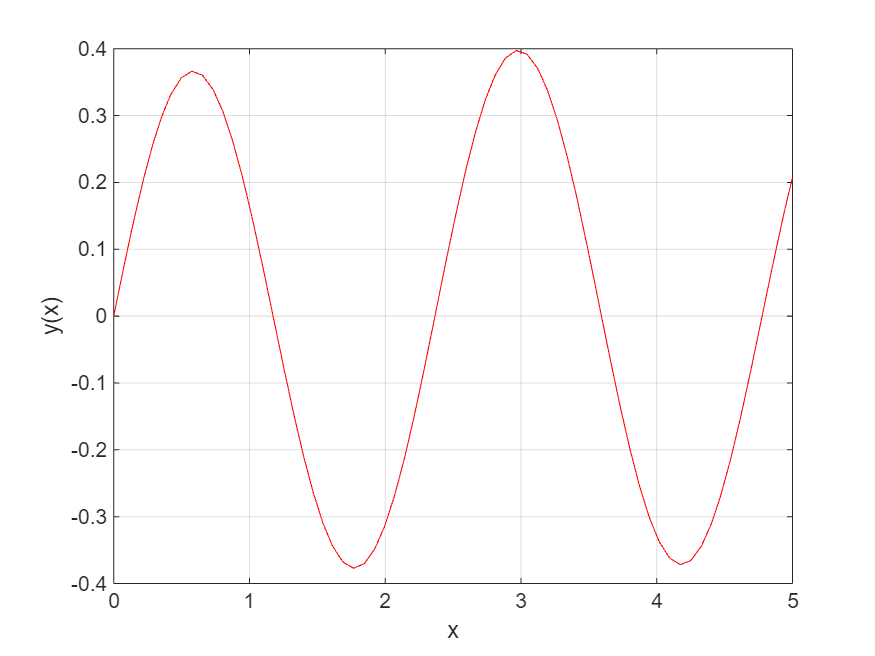

plot(x,v(:,1),'r-')
grid on
xlabel('x'); ylabel('y(x)')

## 5.2. Problemas de contorno

En los problemas de contorno, el objetivo es encontrar una solución para un sistema de ecuaciones diferenciales definida en un intervalo $[a,b]$, que además satisfaga ciertas condiciones adicionales. Estas condiciones no solo dependen de los valores iniciales, como en los problemas de valor inicial, sino que involucran los valores de la solución en **ambos extremos del intervalo** $a \text{ y } b$. 

#### Método de las diferencias finitas

Consideremos un problema de contorno de segundo orden:


$$$$\begin{cases}
y'' = f(x,y,y'), \quad x \in [x_0,x_f]\\
y(x_0) = \alpha, y(x_f) = \beta
\end{cases}
$$$$


El objetivo es encontrar una función $y(x)$ que satisfaga la ecuación diferencial en el intervalo$[x_0 ,\, x_f]$ y que cumpla con las condiciones de contorno $y(x_0) = \alpha, y(x_f) = \beta$.

El método de diferencias finitas es una técnica numérica para aproximar la solución de ecuaciones diferenciales usando una discretización del dominio en un conjunto de puntos. En lugar de resolver la ecuación diferencial de forma analítica, se busca una solución aproximada en estos puntos de la malla.

**Algoritmo**

**1. Discretización del intervalo**: Primero, dividimos el intervalo $[x_0, x_f]$en $N+1$subintervalos del tamaño $h = \frac{x_f - x_0}{N+1}$, donde los puntos de la malla son $$$x_j = x_0 + jh, \quad j =0, \ldots, N+1$$$�.

**2. Aproximación de las derivadas**: Se sustituyen las derivadas de la ecuación diferencial por sus aproximaciones en diferencias finitas


$$\begin{cases} 
v_j  \approx y(x_j)\\

 y'(x_j) = \frac{v_{j+1} - v_{j-1}}{2h} + O(h^2)\\

y''(x_j)= \frac{v_{j+1} -2v_j + v_{j-1}}{h^2} + O(h^2)
\end{cases}$$


**3. Formulación del sistema algebraico**: Sustituyendo esta aproximación en la ecuación diferencial, obtenemos un sistema de ecuaciones en términos de $v_1, v_2, \ldots, v_N$(valores en puntos interiores)�. Para cada punto $x_j$� dentro del intervalo, la ecuación diferencial se convierte en:


$$-\frac{v_{j+1} -2v_j + v_{j-1}}{h^2} +f\left( x_j,v_j,\frac{v_{j+1} - v_{j-1}}{2h} \right) = 0, \quad j = 1, \ldots, N$$


Esto resulta en un sistema de $N$ ecuaciones para los $N$ valores desconocidos $v_1, v_2, \ldots, v_N$�.

**4. Aplicación de las condiciones de contorno**: Las condiciones de contorno $y(x_0) = \alpha, y(x_f) = \beta$ se usan para establecer las condiciones en los puntos extremos:$v_0 = \alpha, \quad
v_{n+1} = \beta$. Estos valores se usan directamente en las ecuaciones del sistema.

**5. Resolución del sistema**: El sistema de ecuaciones resultante se resuelve usando métodos numéricos para obtener las aproximaciones $v_1, v_2, \ldots, v_N$�.

**6. Interpretación de la Solución: **La solución obtenida $v_j$ en cada punto $x_j$es una aproximación numérica a la solución continua $y(x)$ de la ecuación diferencial original. Esta aproximación mejora al refinar la malla (aumentar $N$) y reducir el tamaño del paso $h$.

**Ejemplo**: Problema (lineal) de Transporte Difusivo y Convectivo


$$$$
\begin{cases}
y'' = -4y' +16x^3 -34x + 1, \quad \forall x \in (0,2)\\
y(0) = 4, \; y(2) = 2
\end{cases}
$$$$


Los primeros dos pasos del algoritmo son triviales. 

3. Discretización: para $$j=1, \ldots, N$$:


$$$$-\frac{v_{j+1} -2v_j + v_{j-1}}{h^2}  -4 \frac{v_{j+1} - v_{j-1}}{2h} +16x_j^3 -34x_j + 1 = 0$$$$


Reagrupamos los términos:  


$$$-\left(1 -2h \right) v_{j-1} + 2v_j - \left(1 +2h \right)v_{j+1}  +h^2(16x_j^3 -34x_j + 1) = 0$$$


Obtenemos un sistema lineal tridiagonal que se puede escribir en la forma vectorial:

$$$Av = B$$$, 

donde 

- $$v = (v_1,v_2, \ldots, v_N)^T$$ son valores aproximados en los nodos interiores

- $A = {a_{ij}}$ es una matriz tri-diagonal con los componentes $a_{ii} = 2, \;a_{i, i+1} = - \left(1 +2h \right), \; a_{i, i-1} = -\left(1 -2h \right)$.

- $$B = (b_1, b_2, \ldots, b_N)^T$,$ donde 

$ $b_1 = \alpha(1-2h) -h^2(16x_1^3 -34x_1 + 1)$$, 


$$ $b_j =-h^2(16x_j^3 -34x_j + 1), \quad j = 2, \ldots, n-1$$$



$$ $b_{N} = \beta(1+2h) -h^2(16x_N^3 -34x_N + 1)$$$


Implementación:

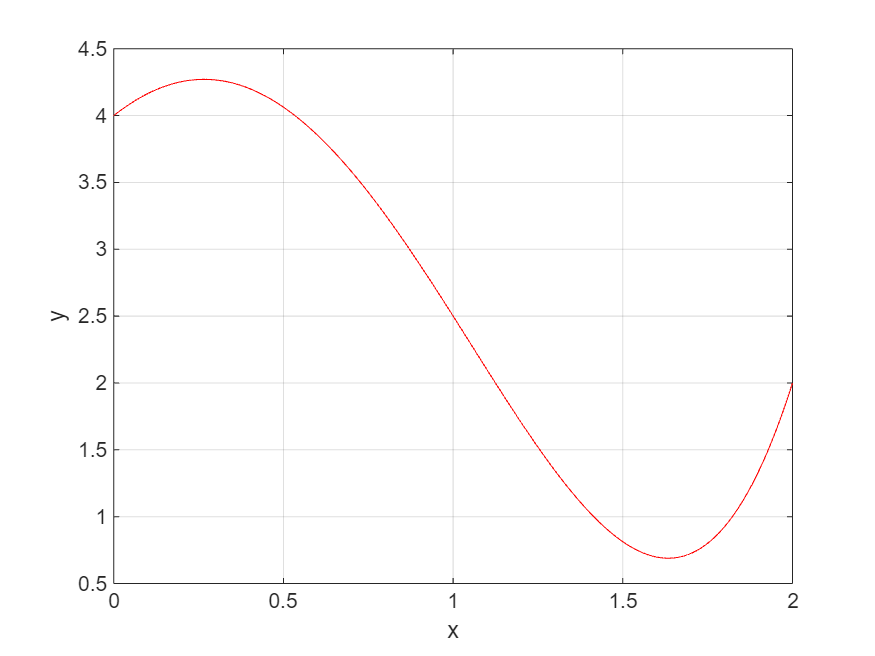

clear all
close all
x0 = 0; xf= 2;          % definimos los extremos del intervalo de integración
alpha = 4; beta = 2;    % condiciones de contorno: y(x0) = alpha, y(xf) = beta
h= 0.01;                % tamaño del paso 
x= x0:h:xf;             % malla de los nodos x_0,..., x_{N+1}
n = length(x)-2;        % n - número de los nodos interiores

% matriz de coeficientes A (tridiagonal):
A = 2*eye(n)-(1-2*h)*diag(ones(1,n-1),-1)- (1+2*h)*diag(ones(1,n-1),+1);

% vector B:
B = -h^2*(16*x(2:end-1).^3 - 34*x(2:end-1) +1)';
B(1) = B(1) + alpha*(1-2*h);
B(end) = B(end) + beta*(1+2*h);

% resolvemos el sistema lineal:
y = A\B;

% añadimos los valores en los extremos del intervalo: y(x0) = alpha, y(xf) = beta
y = [alpha; y; beta];

% representamos graficamente:
plot(x,y,'r-')
grid on
xlabel('x')
ylabel('y')

#### Método de colocación

El método de colocación es una técnica numérica utilizada para aproximar la solución de problemas de contorno (PVF - problemas de valor frontera). La idea principal del método de colocación es encontrar una solución aproximada dentro de un espacio de funciones seleccionadas, de manera que la ecuación diferencial se satisfaga exactamente en ciertos puntos específicos, llamados puntos de colocación.

**Algoritmo**

**1. Definición de funciones de aproximación**

   Se elige un conjunto de funciones base, generalmente polinomios o funciones de tipo spline, que se usarán para construir la solución aproximada. La solución aproximada $\( y(x) \)$ se expresa como una combinación lineal de estas funciones base:


$$   \[
   y(x) \approx y_n(x) = \sum_{j=1}^n c_j \phi_j(x),
   \]$$


   donde$ \( \{\phi_j(x)\} \) $son las funciones base, y $\( \{c_j\} \)$ son los coeficientes a determinar.

**2. Selección de puntos de colocación**

   Se selecciona un conjunto de puntos dentro del dominio, llamados puntos de colocación $\( \{x_i\}_{i=1}^m \)$. Estos puntos son donde se requiere que la solución aproximada cumpla exactamente la ecuación diferencial.

**3. Formulación del sistema de ecuaciones**

   Se sustituye la función aproximada $\( y_n(x) \)$ en la ecuación diferencial y se evalúa en cada uno de los puntos de colocación $\( x_i \)$. Esto genera un sistema de ecuaciones en los coeficientes $\( c_j \)$:


$$   \[
   L(y_n(x_i)) = L\left(\sum_{j=1}^n c_j \phi_j(x_i)\right) = f(x_i), \quad i = 1, 2, \ldots, m,
   \]$$


donde$ \( L \) $es el operador diferencial asociado a la ecuación y$ \( f(x) \)$ es el término no homogéneo de la ecuación diferencial.

**4. Condiciones de contorno**

Las condiciones de contorno se aplican para completar el sistema de ecuaciones. Esto proporciona ecuaciones adicionales necesarias para resolver el sistema en los coeficientes$ \( \{c_j\} \)$.

**5. Resolución del sistema**

El sistema de ecuaciones resultante se resuelve para obtener los coeficientes $\( \{c_j\} \)$. Una vez determinados, se obtiene la solución aproximada $\( y_n(x) \)$.

La función resultante $\( y_n(x) \)$ es una aproximación de la solución real $\( y(x) \)$ de la ecuación diferencial. La precisión de esta aproximación depende del número y la calidad de las funciones base seleccionadas, así como de la elección de los puntos de colocación.

**Método de colocación en MATLAB**

La función [`bvp4c`](https://es.mathworks.com/help/matlab/ref/bvp4c.html) utiliza el método de colocación para resolver el PVF en la forma


$$$$\begin{cases}
y' = f(x,y), \quad x \in [a,b]\\
g(y(a), y(b)) = 0
\end{cases}
$$$$


- `odefun` es un manejador de la función que evalúa el segundo miembro de la ecuación, $$f(x, y)$$. Puede ser el nombre de una función anónima o un manejador de una M-función.

- `ccfun` es un manejador de la función que evalúa las condiciones de contorno$ $g(y(a), y(b))$$

- `initsol` es una estructura que contiene las aproximaciones iniciales. Esta estructura se crea mediante la función `bvpinit.`

`sol` es una estructura que contiene la aproximación numérica calculada, así como algunos datos informativos sobre la resolución. Los campos más importantes de esta estructura  son

- `sol.x` contiene la malla final del intervalo $$[a, b]$$.

- `sol.y` contiene la aproximación numérica de$ $y(x)$$ en los puntos `sol.x.`

- `sol.yp` contiene la aproximación numérica de la derivada $$y'(x)$$ en los puntos `sol.x.`

- `sol.stat` contiene información sobre las iteraciones realizadas por `bvp4c.`

Aproximación inicial:

- `xinit `es un vector que describe una malla inicial. Normalmente bastará con una partición con pocos puntos creada. 

- `yinit `es una aproximación inicial de la solución. Puede ser, o bien un vector, o bien una función.

**Opciones de **`bvp4c`

La función `bvp4c` permite, mediante un argumento opcional, modificar algunas de los parámetros que utiliza el algoritmo por defecto:

Por ejemplo, `RelTol` es el nivel de tolerancia de error relativo que se aplica a todas las componentes del vector residuo. El valor por defecto de `RelTol` es 1.e-3.

Ejemplo: Calculamos una aproximación numérica de la solución del siguiente PVF:


$$$$
\begin{cases}
y_1'= 3y_1-2y_2,
\\
y_2' = -y_1 +\frac{1}{2} y_2, \quad \forall x \in (0,1)\\
y_1(0) = 0, \; y_2(1) = \pi
\end{cases}
$$$$


Algoritmo

1. Definir una función anónima que represente el segundo miembro de la ecuación $$f(x, y)$$:

odefun = @(x,y) [ 3*y(1) - 2*y(2); -y(1) + 0.5*y(2)];

2. Definir una función anónima que evalúe la función que define las condiciones de contorno $$g(y(a),y(b))$$

ccfun = @(ya, yb) [ ya(1); yb(2)-pi];

3. Construir la estructura para proporcionar la aproximación inicial

xinit = linspace(0,1,5); 
yinit = [0; pi];
solinit = bvpinit(xinit, yinit);

4. Utilizar la función `bvp4c` para calcular la solución

sol = bvp4c(odefun, ccfun, solinit);

5.  Representar la solución

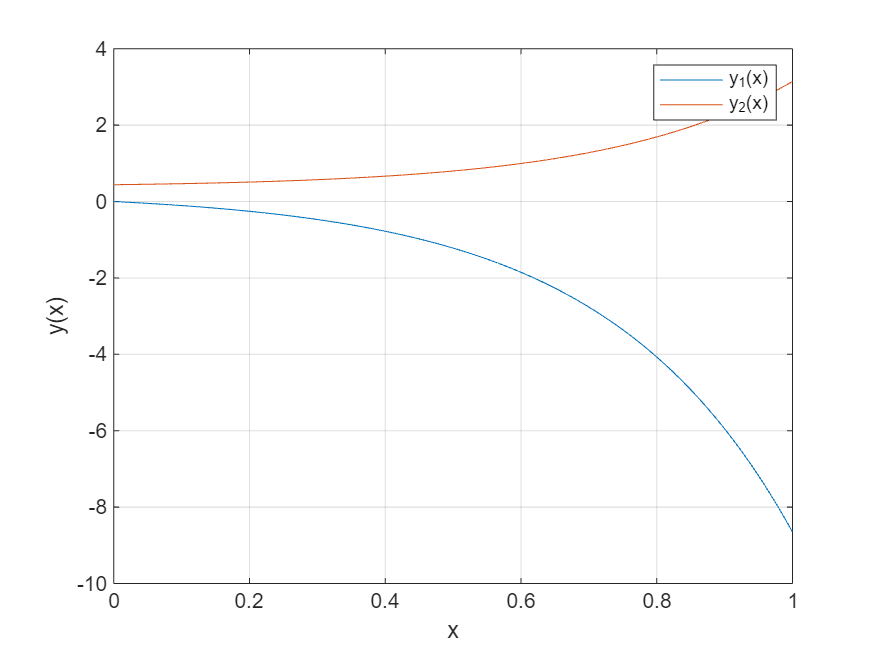

xx = linspace(0,1);
yy = deval(sol, xx);
plot(xx,yy)
grid on
legend('y_1(x)', 'y_2(x)')
xlabel('x')
ylabel('y(x)')

## Bibliografía

- [Chapra S.C.; Canale R. (2015) Métodos Numéricos para Ingenieros. Ed. McGRaw-Hill](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=436963) (Capítulo 25-27)

- [Mathews J.H., Fink K.D. (2000) Métodos Numéricos con MATLAB. Ed. Prentice Hall](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=163396) (Capítulo 9)

Funciones auxiliares

1. Método de Euler:

function[x,y] = euler(f,x0,xf,y0,h)
x = x0:h:xf;
n = length(x);
y = zeros(1, n);
y(1) = y0;
for k = 1:n-1
    y(k+1) = y(k)+h*f(x(k),y(k));
end
end

2. Método de Heun

function[x,y] = heun(f,x0,xf,y0,h)
x = x0:h:xf;
n = length(x);
y = zeros(1, n);
y(1) = y0;
for k = 1:n-1
    predictor = y(k)+h*f(x(k),y(k));
    y(k+1) = y(k) + h* ( f(x(k),y(k)) + f(x(k+1),predictor)  )/2;

end
end

3. Solución del ejercicio:

function [] = eje51()
x0 = 0; xf = 2;
% define la solución analítica: 
sol = @(x) exp(x.^3/3-1.1*x);
y0 = 1;
f = @(x,y) y.*(x.^2-1.1);
fplot(sol,[x0,xf],'k-','LineWidth',1.5)
grid on 
hold on
for h = [0.5, 0.05]
[x,y ] = euler(f,x0,xf,y0,h);
plot(x,y)
end
legend('Solución analítica', 'Euler, h = 0.5', 'Euler, h = 0.05')
hold off
end



4. Solución del ejercicio:

function [] = eje52()
sol = @(x) exp(x.^3/3-1.1*x);
x0 = 0; xf = 2;
y0 = 1;
f = @(x,y) y.*(x.^2-1.1);
fplot(sol,[x0,xf],'k-','LineWidth',1.5)
grid on 
hold on
h = 0.5;
% Método de Euler:
[x,y_euler] = euler(f,x0,xf,y0,h);
plot(x,y_euler,'b-')

% Método de Heun:
[x,y_heun] = heun(f,x0,xf,y0,h);
plot(x,y_heun,'g-')
legend('Solución analítica', 'Euler, h = 0.5', 'Heun, h = 0.5')
hold off
end